Task 0

I dont mind if the lecture is digital or physical, but I would really like if the lectures are recorded as the lecture collides with something else for me. I read the powerpoints but I dont feel like this is sufficent. 

And I think either the assignments should be out earlier or the assignment lecture should be moved to monday or tuesday, as the time from getting the assignment to the assignment lecture/aid is very short.

Loading in the files and setting global variables given in assignment.

invivo_data = load("invivoData.mat");
sim_data = load("simdata.mat");
c = 1540;

Task 1

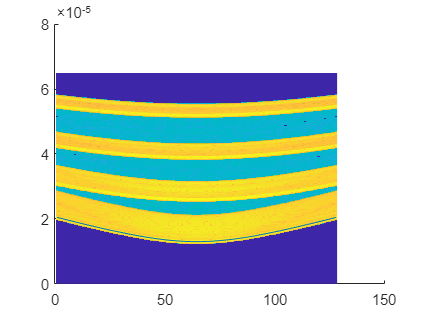

sim_elpos = sim_data.elPosX;
sim_Rf = sim_data.RFdata;
sim_Rf_t = sim_data.RF_t;
x1 = 0;
z1 = 0.01; %meter
TOF_sim = TOF(z1,c,x1,sim_elpos);
[sim_rows, sim_cols] = size(sim_Rf);
sim_xaxis = linspace(1,sim_cols,sim_cols);
%colormap(gray(256));
%imagesc(sim_Rf');
figure(3);
imagesc('XData',sim_xaxis,'YData',sim_Rf_t,'CData', log(abs(sim_Rf)));
hold on;
plot(TOF_sim);


x = linspace( -2e-2, 2e-2, 256); %x-coordinates
zlen = 512;
z = linspace( 0, 4.5e-2, zlen); %z-coordinates
z = permute(z, [1 3 2]);
[X, Z] = meshgrid( x, z); %make X and Z matrices
% initialize TOF-matrix
TOF_sim_0 = zeros( length(z), length(x), length(sim_elpos) );
% for x_axis = 1:lenght(x)
%     for depth = 1:lenght(z)
%         TOF_sim_mat(depth,x_axis,)
TOF_sim_mat = TOF(z,c,x,sim_elpos);

TOF_sim_mat = permute(TOF_sim_mat,[3,2,1])

TOF_sim_mat = TOF_sim_mat(:,:,1) =

   1.0e-04 *

    0.0062    0.0052    0.0041    0.0031    0.0021    0.0011    0.0001    0.0010    0.0020    0.0030    0.0040    0.0050    0.0061    0.0071    0.0081    0.0091    0.0101    0.0111    0.0122    0.0132    0.0142    0.0152    0.0162    0.0173    0.0183    0.0193    0.0203    0.0213    0.0224    0.0234    0.0244    0.0254    0.0264    0.0274    0.0285    0.0295    0.0305    0.0315    0.0325    0.0336    0.0346    0.0356    0.0366    0.0376    0.0386    0.0397    0.0407    0.0417    0.0427    0.0437    0.0448    0.0458    0.0468    0.0478    0.0488    0.0499    0.0509    0.0519    0.0529    0.0539    0.0549    0.0560    0.0570    0.0580    0.0590    0.0600    0.0611    0.0621    0.0631    0.0641    0.0651    0.0662    0.0672    0.0682    0.0692    0.0702    0.0712    0.0723    0.0733    0.0743    0.0753    0.0763    0.0774    0.0784    0.0794    0.0804    0.0814    0.0824    0.0835    0.0845    0.0855    0.0865    0.0875    0.0886    0.0896

Task 2 

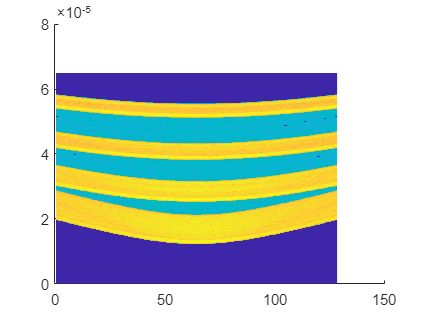

Error using plot
Data cannot have more than 2 dimensions.

bf_sim_rf = sum(sim_Rf,2); %what is the different between summing between axis 1 or 2. Seem to give the same envelope but different length?

delayed_data = interpTOF(sim_Rf, sim_Rf_t, TOF_sim_mat);
sim_envelope = abs(hilbert(bf_sim_rf)); %not sure if it should be the sim_rf data here
figure(2);
plot(sim_envelope);

Functions

function t = TOF(z,c,x,elposx)
    t_tx = z/c;
    t_rx = (sqrt((x-elposx).^2 + z.^2))/c;
    t = t_tx+t_rx;
end